# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; %21; % Magnitude/Amplitude of droplet
c1 = 0.001264379882813;
c2 = 0.016807519531250;
tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
xI0 = 5;
xB0 = 10;
xC0 = 15;

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;

## **2) **

**Solutions**

Inside

[tSpanI,D1,D2,X,H0I,myObjective_Possition,conds_SolI,...
    fvalI,exitflagI,outputI,historyI,HistoryI,h_SolI,H_SolI,outputsI]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xI0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          68.8189         
     1            2          68.8189         initial simplex
     2            4          61.0817         expand
     3            6           51.267         expand
     4            8          23.6331         expand
     5           10          9.48885         reflect
     6           12          9.48885         contract inside
     7           14          3.60606         contract inside
     8           16          3.60606         contract inside
     9           18          3.60606         contract outside
    10           20          3.60606         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 5.514748 seconds.



struct2table(outputsI);

nI = size(historyI);
nI1 = nI(1)-2;
dataHI = historyI(2:end)';
dataHIi = abs(historyI(2:end))';
lineHI = 0:1:nI1;
lineHIi = 0:1:nI1;
[pI,SI,muI] = polyfit(lineHI,dataHI,1);
[pHI,deltaI] = polyval(pI,lineHI,SI,muI);

xIi = linspace(0, nI1, 100); 
yIi = interp1(lineHIi, dataHIi, xIi, 'spline', 'extrap');


Boarder

[tSpanB,D1,D2,X,H0B,myObjective_Possition,conds_SolB,...
    fvalB,exitflagB,outputB,historyB,HistoryB,h_SolB,H_SolB,outputsB]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xB0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          102.704         
     1            2          102.704         initial simplex
     2            4          100.187         expand
     3            6           88.235         expand
     4            8          44.0115         expand
     5           10          16.0203         reflect
     6           12          16.0203         contract inside
     7           14          3.60606         contract inside
     8           16          3.60606         contract inside
     9           18          3.60606         contract outside
    10           20          3.60606         contract outside
    11           22          3.60606         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 5.348560 seconds.



struct2table(outputsB);

nB = size(historyB);
nB1 = nB(1)-2;
dataHB = historyB(2:8)';
dataHBi = abs(historyB(2:end))';
lineHB = 0:1:6;
lineHBi = 0:1:nB1;
[pB,SB,muB] = polyfit(lineHB,dataHB,1);
[pHB,deltaB] = polyval(pB,lineHB,SB,muB);

xBi = linspace(1, nB1, 100); 
yBi = interp1(lineHBi, dataHBi, xBi, 'spline', 'extrap');


Outside

[tSpanC,D1,D2,X,H0C,myObjective_Possition,conds_SolC,...
    fvalC,exitflagC,outputC,historyC,HistoryC,h_SolC,H_SolC,outputsC]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xC0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          102.999         
     1            2          102.999         initial simplex
     2            4          102.994         reflect
     3            6          102.994         contract inside
     4            9          102.994         shrink
     5           12          102.994         shrink
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 3.007232 seconds.



struct2table(outputsC);

nC = size(historyC);
nC1 = nC(1)-2;
dataHC = historyC(2:end)';
dataHCi = abs(historyC(2:end))';
lineHC = 0:1:nC1;
lineHCi = 0:1:nC1;
[pC,SC,muC] = polyfit(lineHC,dataHC,1);
[pHC,deltaC] = polyval(pC,lineHC,SC,muC);

xCi = linspace(0, nC1, 100); 
yCi = interp1(lineHCi, dataHCi, xCi, 'spline', 'extrap');


**Inside Figures**

Fig. 1

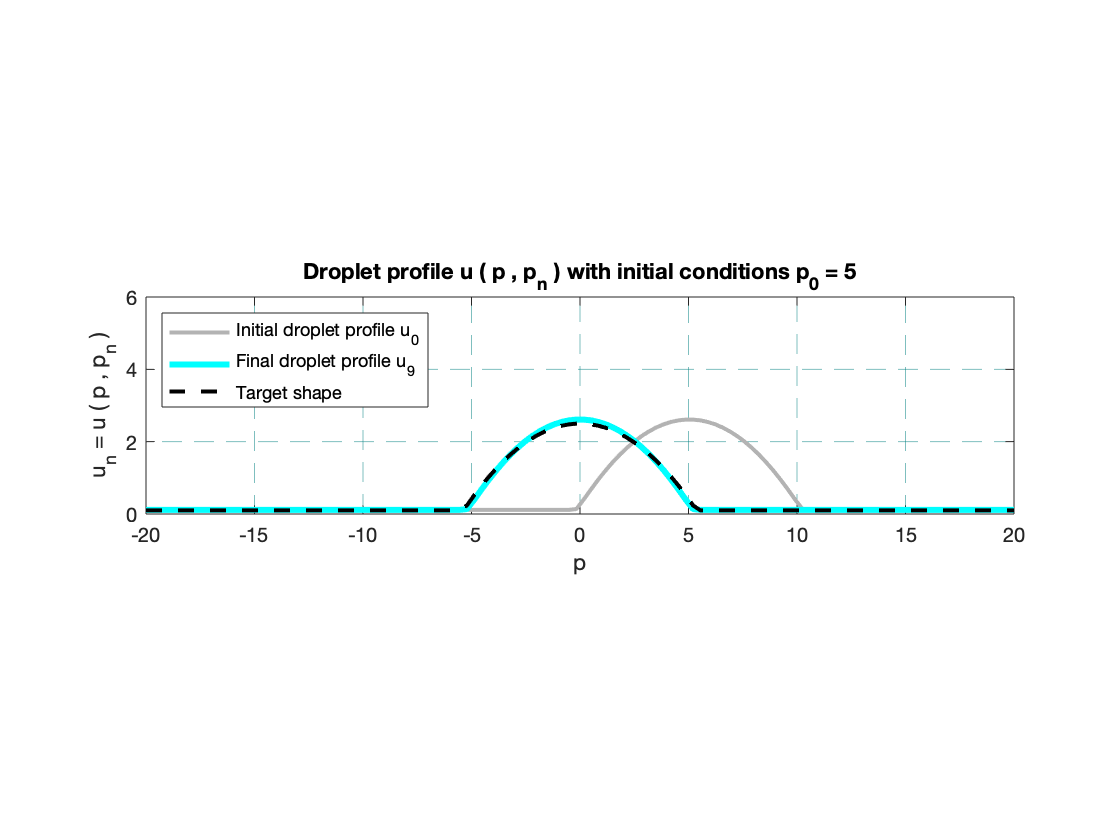

figure;

hold on
plot(X,H0I,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_SolI,'c-','linewidth',3);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , p_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_9',...
    'Target shape',...
    'Location','northwest');
title('Droplet profile u ( p , p_n ) with initial conditions p_0 = 5');
hold off

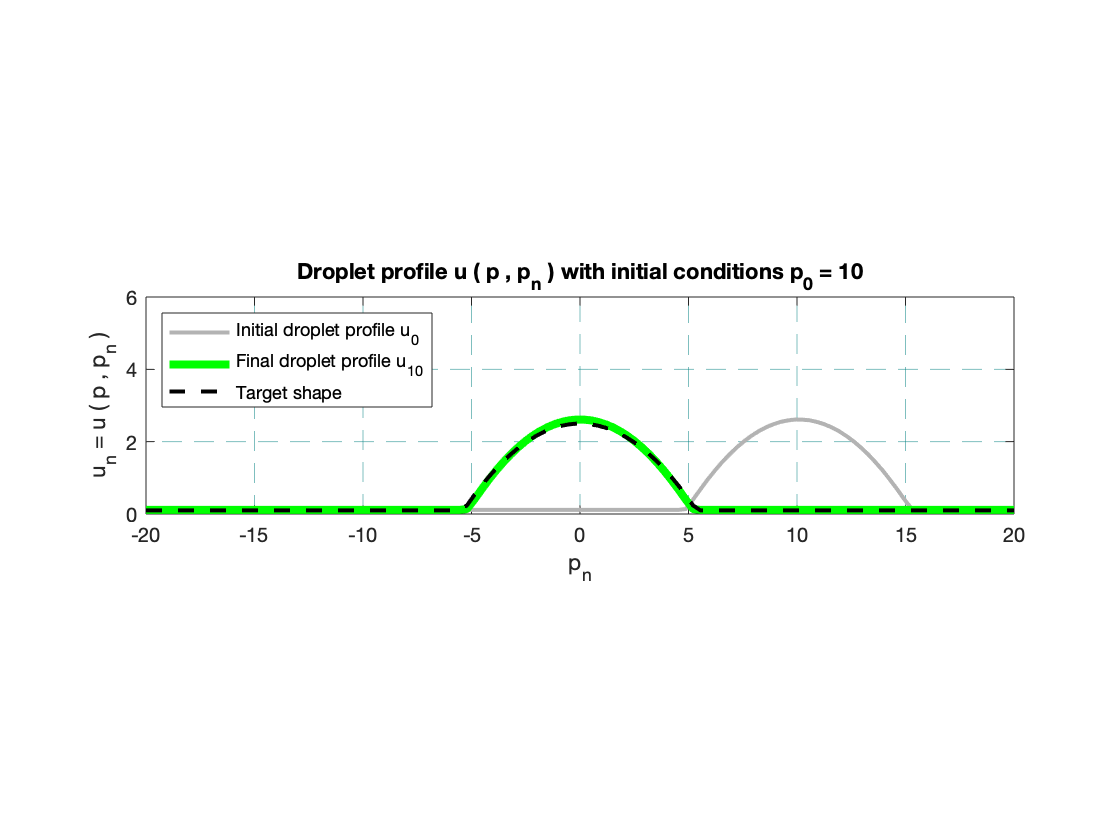


figure;
hold on
plot(X,H0B,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_SolB,'g-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p_n');
ylabel('u_n = u ( p , p_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{10}',...
    'Target shape',...
    'Location','northwest');
title('Droplet profile u ( p , p_n ) with initial conditions p_0 = 10');
hold off

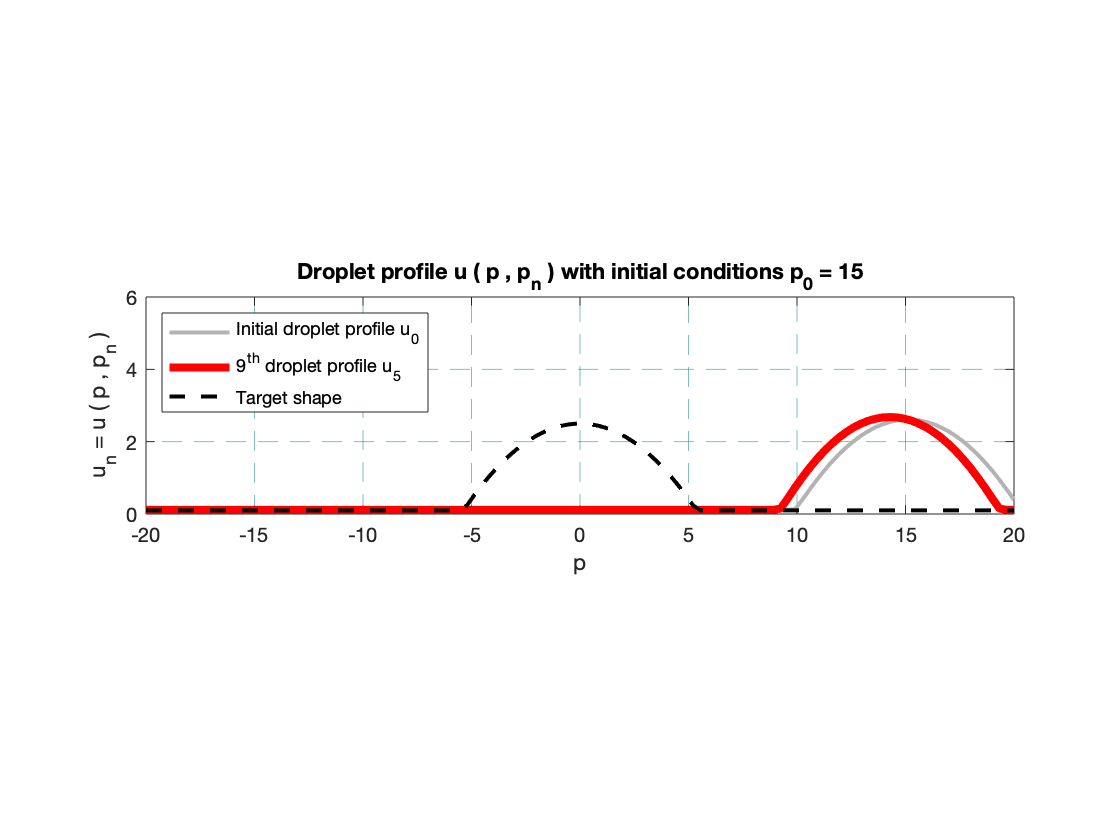


figure;
hold on
plot(X,H0C,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_SolC,'r-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , p_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    '9^{th} droplet profile u_5',...
    'Target shape',...
    'Location','northwest');
title('Droplet profile u ( p , p_n ) with initial conditions p_0 = 15');
hold off

**Joint Figures**

Joint Figure

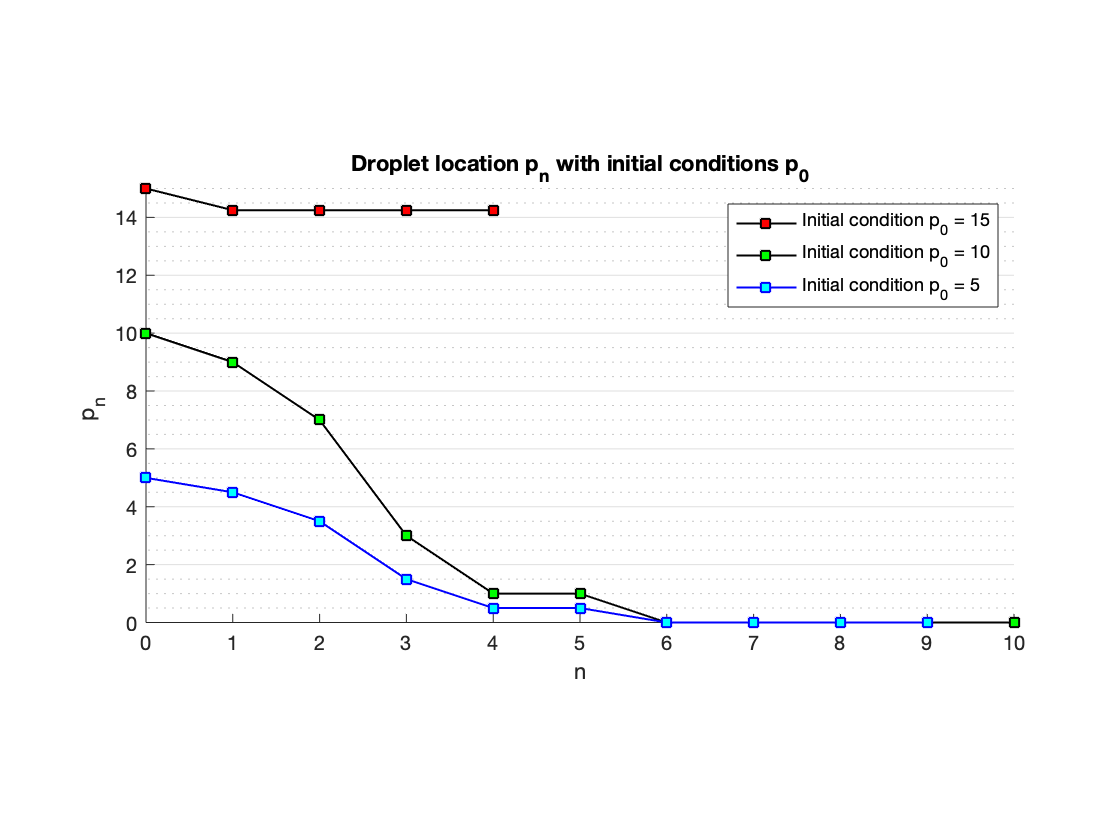

figure;
hold on
plot(0:4,dataHCi,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:10,dataHBi,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:9,dataHIi,'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n ');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 5','Location','northeast');
title('Droplet location p_n with initial conditions p_0');
set(gca,'xtick',0:1:21);
set(gca,'ytick',0:2:100);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

Fig. 1

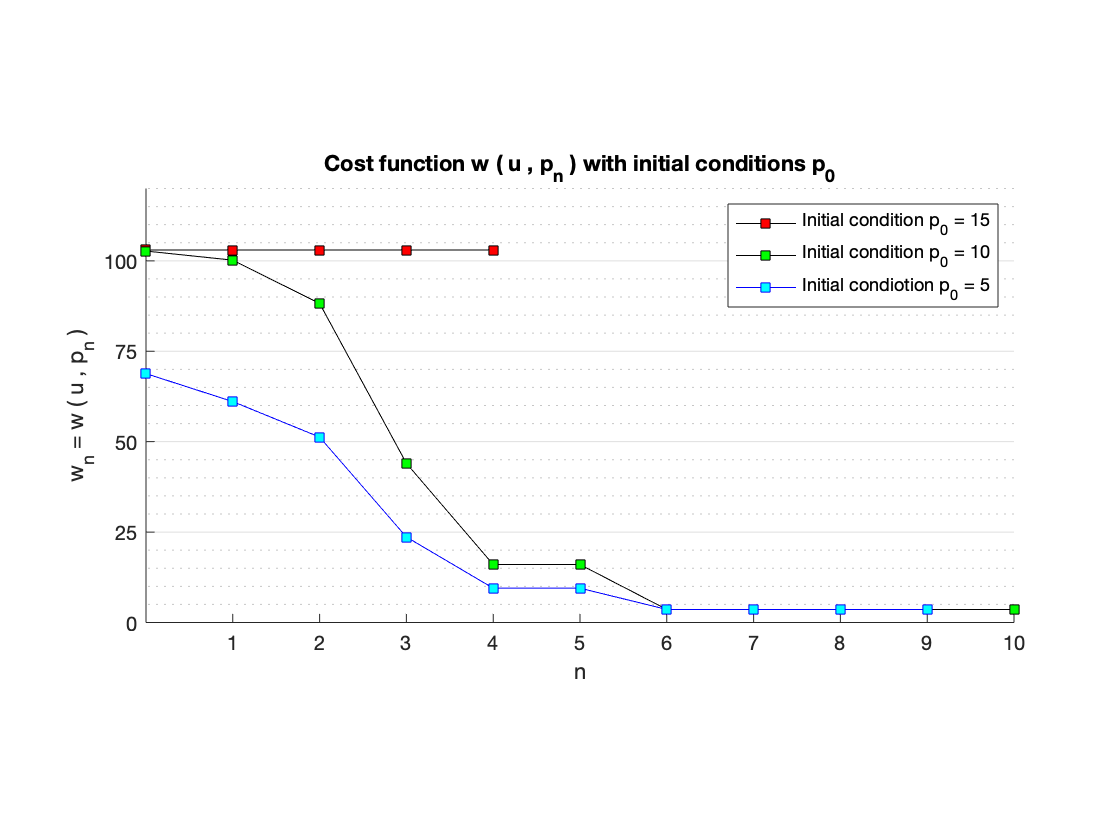

figure;
hold on
plot(lineHCi,HistoryC(2:end),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r');
plot(lineHBi,HistoryB(2:end),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g');
plot(lineHIi,HistoryI(2:end),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c');
ylabel('w_n = w ( u , p_n )');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condiotion p_0 = 5','Location','northeast');
title('Cost function w ( u , p_n ) with initial conditions p_0');
set(gca,'xtick',1:1:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

TI = struct2table(outputsI)

TI = 11×4 table
    iteration    funccount     fval          procedure      
    _________    _________    ______    ____________________

        0            1        68.819    {0×0 char          }
        1            2        68.819    {'initial simplex' }
        2            4        61.082    {'expand'          }
        3            6        51.267    {'expand'          }
        4            8        23.633    {'expand'          }
        5           10        9.4888    {'reflect'         }
        6           12        9.4888    {'contract inside' }
        7           14        3.6061    {'contract inside' }
        8           16        3.6061    {'contract inside' }
        9           18        3.6061    {'contract outside'}
       10           20        3.6061    {'contract inside' }


filename = 'TI.xlsx';
writetable(TI,filename,'Sheet',1,'Range','D1')

TB = struct2table(outputsB)

TB = 12×4 table
    iteration    funccount     fval          procedure      
    _________    _________    ______    ____________________

        0            1         102.7    {0×0 char          }
        1            2         102.7    {'initial simplex' }
        2            4        100.19    {'expand'          }
        3            6        88.235    {'expand'          }
        4            8        44.011    {'expand'          }
        5           10         16.02    {'reflect'         }
        6           12         16.02    {'contract inside' }
        7           14        3.6061    {'contract inside' }
        8           16        3.6061    {'contract inside' }
        9           18        3.6061    {'contract outside'}
       10           20        3.6061    {'contract outside'}
       11           22        3.6061    {'contract ins

filename = 'TB.xlsx';
writetable(TB,filename,'Sheet',1,'Range','D1')

TC = struct2table(outputsC)

TC = 6×4 table
    iteration    funccount     fval          procedure     
    _________    _________    ______    ___________________

        0            1           103    {0×0 char         }
        1            2           103    {'initial simplex'}
        2            4        102.99    {'reflect'        }
        3            6        102.99    {'contract inside'}
        4            9        102.99    {'shrink'         }
        5           12        102.99    {'shrink'         }


filename = 'TC.xlsx';
writetable(TC,filename,'Sheet',1,'Range','D1')
